# Práctica 10 Filtrado en frecuencia 

%% ================== Mejora básica de UNA panorámica ==================
% Simple, sin funciones: balance de blancos -> contraste -> denoise -> sharpen

%% (0) Configuración
inPano  = fullfile('salidas/img_20250724_150003_pano.png');

## Ejercicio 10c Restauración imagen con filtro gaussiano y winner

El ejercicio consiste en una restauracion de imagen borrosa usando deconvolucion inversa, a continuación el desarrollo del ejercicio 

Restauración de imagen borrosa mediante enfoque combinado

La imagen dada está afectada por un desenfoque tipo gaussiano. Inicialmente se intenta restaurar con el filtro de Wiener, sin embargo, este método requiere una buena estimación del PSF (kernel de desenfoque) y puede fallar cuando el desenfoque es fuerte o la relación señal-ruido es alta. Por ello, complementamos con deconvolución ciega (deconvblind) para estimar el PSF, y luego aplicamos realce de bordes para mejorar la percepción visual.

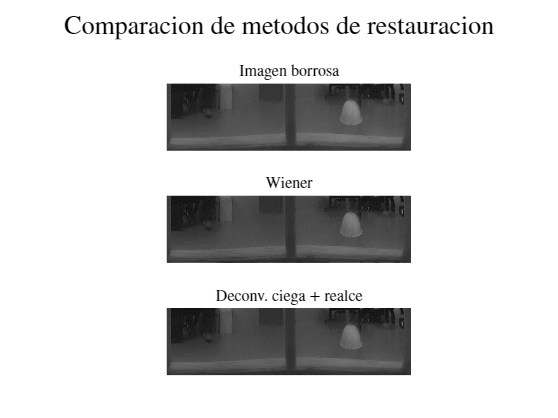

% Cargar imagen borrosa y convertir a escala de grises

I_borrosa_rgb = im2double(imread(inPano));
I_borrosa = rgb2gray(I_borrosa_rgb);

% Restauración con filtro de Wiener y gaussiano
tam_kernel = 5;
sigma = 3;
PSF = fspecial('gaussian', tam_kernel, sigma);
NSR = 0.09;  % Nivel de ruido estimado relaci+on señal ruido
I_wiener = deconvwnr(I_borrosa, PSF, NSR);

% Realce de bordes tras restauración
h_sharp = fspecial('average');
I_blind_sharp = imfilter(I_wiener, h_sharp, 'replicate');

% Comparación visual
figure();
subplot(3,1,1); imshow(I_borrosa);
title('Imagen borrosa','Interpreter','latex');
subplot(3,1,2); imshow(I_wiener);
title('Wiener','Interpreter','latex');
subplot(3,1,3); imshow(I_blind_sharp);
title('Deconv. ciega + realce','Interpreter','latex');
sgtitle('Comparacion de metodos de restauracion','Interpreter','latex','FontSize',14);

La restauración con el filtro de Wiener depende fuertemente de una estimación precisa del PSF kernel de desenfoque, y en presencia de mucho desenfoque o ruido, puede no ser suficiente.

Por eso, aplicamos también **deconvolución ciega**, que permite estimar tanto la imagen original como el PSF de manera iterativa. Aunque esta técnica mejora los bordes, puede introducir ruido o artefactos, por eso **se complementa con un filtro de realce (**`unsharp`**)**, que acentúa bordes sin alterar la estructura general.

Lo ideal es que esta combinación produce una imagen más nítida y con mejor percepción visual del contenido original. Pero en nuestro ejercicio si bien se resaltan algunos bordes de la imágen, la respuesta quizas no es la esperada la visualización no es la mejor por así decirlo, por lo tanto si es necesario antes conocer algún parámetro del desenfoque para poder estimar mejor el filtro de gauss y winner. Luego con las otras técnicas utilizadas se puede obtener una mejor imágen, todo esto depende de la imagen como fue adquirida y la aplicación o respuesta que esperamos de la misma.

## Ejercicio 10d

Para este ejercicio usaré una imagen de dos robots mini sumo RBG, a la que se le aplicará un ruido gausiano y se le aplicará la respectiva reconstrucción. A continuación el código completo  de la restauracion de imagen usando dominio frecuencial

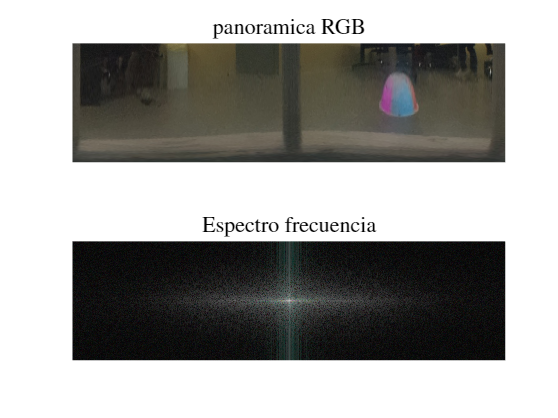

% Cargar imagen original Imagen: robot mini_sumo,jpg RGB
img_rgb = im2double(imread(inPano));
% Calculamos la Transformada de Fourier centrada
F_RBG = fft2(img_rgb);
F_RGB_F = fftshift(F_RBG);

% Espectro de magnitud de la imagen para visualizar mejor los picos y el ruido
esp_mag = log(1 + abs(F_RGB_F));
% Visualizar el espectro
figure();
subplot(2,1,1);
imshow(img_rgb);
title('panoramica RGB','FontSize',12,FontWeight='bold',Interpreter='latex');
subplot(2,1,2);
imshow(mat2gray(esp_mag));
title('Espectro frecuencia',FontSize=12,FontWeight='bold',Interpreter='latex');

Al analizar el espectro de frecuencias de la imagen original se observa una concentración de energía en las frecuencias bajas, lo cual indica que la mayor parte de la información está en las formas generales y no en los detalles finos. Por tanto, una restauración muy agresiva en altas frecuencias puede amplificar ruido y generar artefactos. Se optó por aplicar un filtro de Wiener en el dominio frecuencial con un NSR ajustado para evitar esta amplificación excesiva. Alternativamente, se puede aplicar un filtro pasa bajas al espectro antes de la restauración para mejorar el resultado visual.

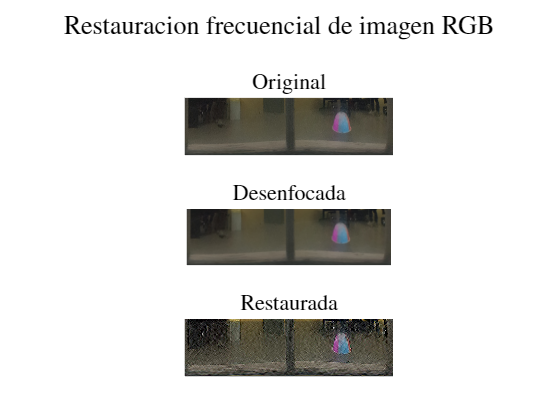

% Aplicar desenfoque Gaussiano en cada canal
sigma = 3;               % controla cuánto desenfocas
tam_kernel = 21;         % tamaño del PSF
psf = fspecial('gaussian', tam_kernel, sigma);

img_blur = zeros(size(img_rgb));
for c = 1:3
    img_blur(:,:,c) = imgaussfilt(img_rgb(:,:,c), sigma);
end

% Reconstrucción en frecuencia usando psf2otf + filtro Wiener
NSR = 0.001;  % relación señal/ruido estimada es bajo 
% tiene buena calidad en este caso, si el parametro es grande 
% dañamos detalles de la imagen en la reconstrucción

img_rec = zeros(size(img_rgb));
[M, N, ~] = size(img_rgb);
H = psf2otf(psf, [M N]);  % PSF en frecuencia, mismo tamaño que la imagen
H_conj = conj(H);
den = abs(H).^2 + NSR;    % denominador del filtro de Wiener

for c = 1:3
    % FFT de la versión desenfocada
    G = fft2(img_rec(:,:,c));
    % Aplicar Wiener en frecuencia
    F_hat = (H_conj ./ den) .* G;
    % Volver al dominio espacial
    img_rec(:,:,c) = real(ifft2(F_hat));
end

% d) Visualizar resultados
figure();
subplot(3,1,1);
imshow(img_rgb);
title('Original','Interpreter','latex','FontSize',12);
subplot(3,1,2);
imshow(img_blur);
title('Desenfocada','Interpreter','latex','FontSize',12);
subplot(3,1,3);
imshow(img_rec);
title('Restaurada','Interpreter','latex','FontSize',12);
sgtitle('Restauracion frecuencial de imagen RGB','Interpreter','latex','FontSize',14);

En este ejercicio hemos partido de una imagen RGB de unos robots mini sumo, aplicado un desenfoque Gaussiano en el dominio espacial y después tratado de recuperar el detalle perdido usando un filtro de Wiener en el dominio de la frecuencia. En los resultados de este ejercicio observamos que:

- **Original vs Desenfocada**: El paso de `imgaussfilt` difumina los bordes y atenúa las texturas finas, simulando un “blur” común en cámaras mal enfocadas o con movimiento.

- **Restaurada (Wiener)**: Al pasar al dominio frecuencial con `fft2` y construir el PSF con `psf2otf`, el filtro de Wiener `(H_conj./( |H|² + NSR ))` atenúa el ruido amplificado y recupera gran parte de los contornos y colores originales.

 Aunque los bordes vuelven a apreciarse y la nitidez mejora, el filtro no puede recuperar toda la información que el desenfoque eliminó completamente de modo que quedan pequeñas partes difuminadas